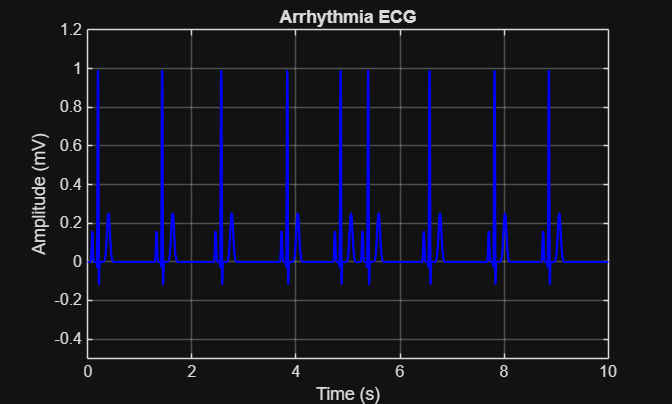

duration = 10;
fs       = 1000;
t        = 0 : 1/fs : duration;
ecg      = zeros(size(t));

% Wave parameters
a = [ 0.25, -0.2,  1.6, -0.4,  0.4];
b = [ 0.09, 0.185, 0.20, 0.215, 0.40];
c = [0.015, 0.008, 0.012, 0.008, 0.04];

% Random beat onsets (irregular spacing)
onsets = cumsum([0,  0.5 + 0.8*rand(1, 8)]);
onsets = onsets(onsets < duration - 0.5);

% Build ECG
for k = onsets
    for i = 1:5
        ecg = ecg + (a(i)/1.6) .* exp(-((t - k - b(i))./c(i)).^2);
    end
end

% Plot
figure;
plot(t, ecg, 'b', 'LineWidth', 1.5);
xlabel('Time (s)'); ylabel('Amplitude (mV)');
title('Arrhythmia ECG'); grid on;
ylim([-0.5, 1.2]);


% ---- Package for Simulink ----
ecg_sim.time               = t';
ecg_sim.signals.values     = ecg';
ecg_sim.signals.dimensions = 1;

## Heart beats & R-R Peaks Calculations

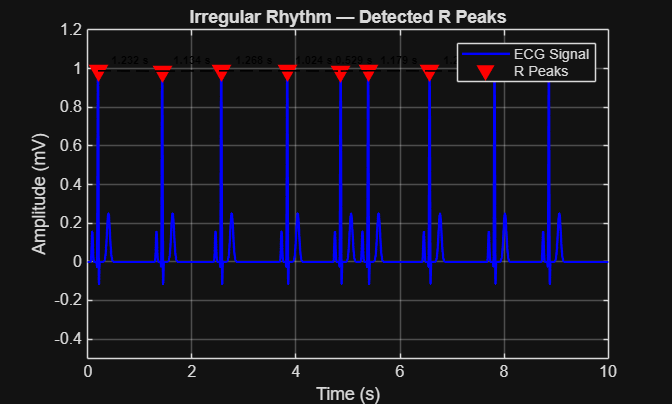

%% =====================================================
% Member 3 — R Peak Detection (Irregular Rhythm)
%% =====================================================

%% Detect R peaks
[pks_irr, locs_irr] = findpeaks(ecg, ...
    'MinPeakDistance', round(0.3*fs), ...   % min 0.3 s apart — allows variable rate
    'MinPeakProminence', 0.25);             % reject noise / small waves

%% Plot ECG with detected R-peaks
figure;
plot(t, ecg, 'b', 'LineWidth', 1.5);
hold on;
plot(t(locs_irr), pks_irr, 'rv', 'MarkerSize', 10, 'MarkerFaceColor', 'r');

%% Draw lines between consecutive R peaks with RR interval labels
RR_irr = diff(t(locs_irr));        % seconds
for i = 1:length(RR_irr)
    x1 = t(locs_irr(i));
    x2 = t(locs_irr(i+1));
    y1 = pks_irr(i);
    y2 = pks_irr(i+1);
    % Draw line between R peaks
    plot([x1 x2], [y1 y2], 'k--', 'LineWidth', 1);
    % Label with RR interval at midpoint (slightly above the line)
    xm = (x1 + x2) / 2;
    ym = (y1 + y2) / 2 + 0.05;
    text(xm, ym, sprintf('%.3f s', RR_irr(i)), ...
        'HorizontalAlignment', 'center', ...
        'FontSize', 7, 'Color', 'k', 'FontWeight', 'bold');
end
hold off;

xlabel('Time (s)'); ylabel('Amplitude (mV)');
title('Irregular Rhythm — Detected R Peaks');
legend('ECG Signal', 'R Peaks');
grid on; ylim([-0.5, 1.2]);


%% BPM per beat (instantaneous heart rate)
HR_irr     = 60 ./ RR_irr;         % one BPM value per interval
meanHR_irr = mean(HR_irr);

%% Display results
disp('--- Irregular Rhythm R-Peak Results ---')

--- Irregular Rhythm R-Peak Results ---


disp(['Number of R-peaks:         ', num2str(length(pks_irr))])

Number of R-peaks:         9


disp(['RR Intervals (s):          ', num2str(RR_irr(:)')])

RR Intervals (s):          1.232       1.134       1.268       1.024       0.529       1.179       1.247       1.043


disp(['Instantaneous BPM:         ', num2str(HR_irr(:)')])

Instantaneous BPM:         48.7013      52.91005      47.31861      58.59375      113.4216      50.89059      48.11548      57.52637


disp(['Mean Heart Rate (bpm):     ', num2str(meanHR_irr)])

Mean Heart Rate (bpm):     59.6847


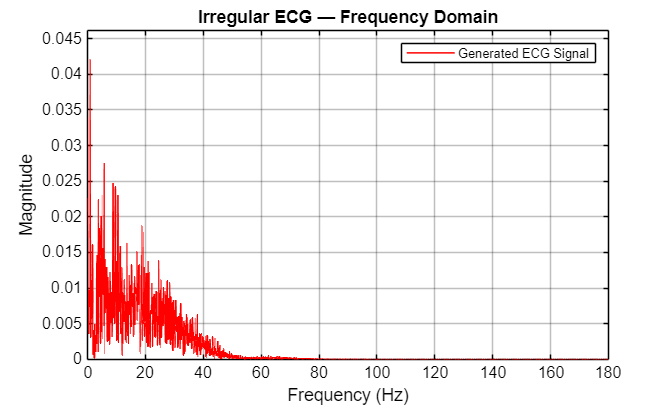

%% =====================================================
%  Irregular Rhythm — Generated ECG (Frequency Domain)
%% =====================================================
L_gen = length(ecg);
Y_gen = fft(ecg);
P2_gen = abs(Y_gen / L_gen);
P1_gen = P2_gen(1:floor(L_gen/2)+1);
P1_gen(2:end-1) = 2 * P1_gen(2:end-1);
f_gen = fs * (0:floor(L_gen/2)) / L_gen;

figure;
plot(f_gen, P1_gen, 'r', 'LineWidth', 1.0);
ttl = title('Irregular ECG — Frequency Domain');
xlabel('Frequency (Hz)');
ylabel('Magnitude');
grid on;
xlim([0 180]);
ylim([0 max(P1_gen)*1.1]);

set(gcf, 'color', 'w');
set(gca, 'color', 'w', 'XColor', 'k', 'YColor', 'k');
lgd = legend('Generated ECG Signal', 'Location', 'northeast');
lgd.Color = 'w'; lgd.TextColor = 'k'; lgd.EdgeColor = 'k'; lgd.FontSize = 8;
ttl.Color = 'k';

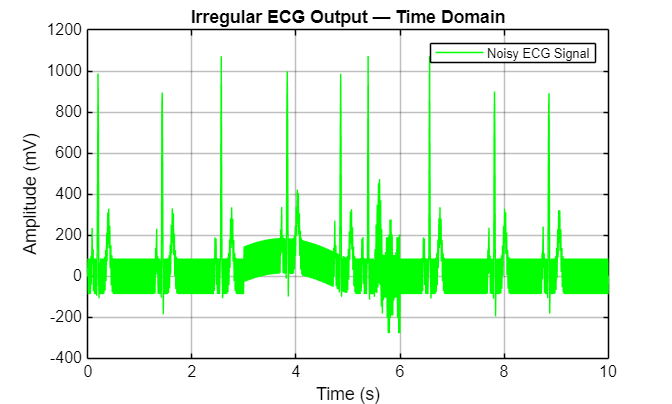


%% =====================================================
%  Irregular Rhythm — Noisy/Amplified (Simulink Output)
%% =====================================================
t_out   = out.ecg_amplified.Time;
ecg_out = out.ecg_amplified.Data(:)';
fs_out  = 1 / mean(diff(t_out));

% TIME DOMAIN
figure;
plot(t_out, ecg_out, 'g');
ttl = title('Irregular ECG Output — Time Domain');
xlabel('Time (s)');
ylabel('Amplitude (mV)');
grid on;

set(gcf, 'color', 'w');
set(gca, 'color', 'w', 'XColor', 'k', 'YColor', 'k');
lgd = legend('Noisy ECG Signal', 'Location', 'northeast');
lgd.Color = 'w'; lgd.TextColor = 'k'; lgd.EdgeColor = 'k'; lgd.FontSize = 8;
ttl.Color = 'k';
exportgraphics(gcf, 'irregular_ecgNoisy_TimeDomain.png', 'Resolution', 300);

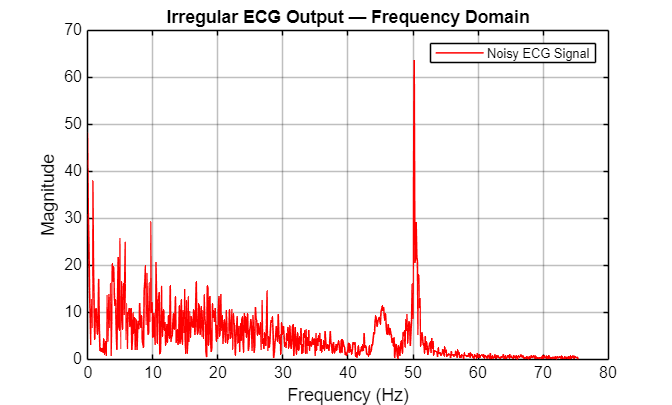


% FREQUENCY DOMAIN
L_out   = length(ecg_out);
Y_out   = fft(ecg_out);
P2_out  = abs(Y_out / L_out);
P1_out  = P2_out(1:floor(L_out/2)+1);
P1_out(2:end-1) = 2 * P1_out(2:end-1);
f_out   = fs_out * (0:floor(L_out/2)) / L_out;

figure;
plot(f_out, P1_out, 'r', 'LineWidth', 1.0);
ttl = title('Irregular ECG Output — Frequency Domain');
xlabel('Frequency (Hz)');
ylabel('Magnitude');
grid on;

set(gcf, 'color', 'w');
set(gca, 'color', 'w', 'XColor', 'k', 'YColor', 'k');
lgd = legend('Noisy ECG Signal', 'Location', 'northeast');
lgd.Color = 'w'; lgd.TextColor = 'k'; lgd.EdgeColor = 'k'; lgd.FontSize = 8;
ttl.Color = 'k';


%% =====================================================
%  Irregular Rhythm — Filtering (HP + Notch + LP)
%% =====================================================

% FILTER 1: High-Pass — Remove Baseline Wander (0.5 Hz)
order_hp = 4;
fc_hp    = 0.5;
Wn_hp    = fc_hp / (fs_out/2);
[b_hp, a_hp] = butter(order_hp, Wn_hp, 'high');
ecg_hp = filtfilt(b_hp, a_hp, ecg_out);

% FILTER 2: Notch — Remove Powerline at 50 Hz
notch_freq = 50;
bandwidth  = 1;
Wn_notch   = [notch_freq - bandwidth/2, notch_freq + bandwidth/2] / (fs_out/2);
[b_n, a_n] = butter(2, Wn_notch, 'stop');
ecg_notch  = filtfilt(b_n, a_n, ecg_hp);

% FILTER 3: Low-Pass — Remove Muscle Artifact at 45 Hz (cutoff 40 Hz)
order_lp = 4;
fc_lp    = 40;
Wn_lp    = fc_lp / (fs_out/2);
[b_lp, a_lp] = butter(order_lp, Wn_lp, 'low');
ecg_clean = filtfilt(b_lp, a_lp, ecg_notch);

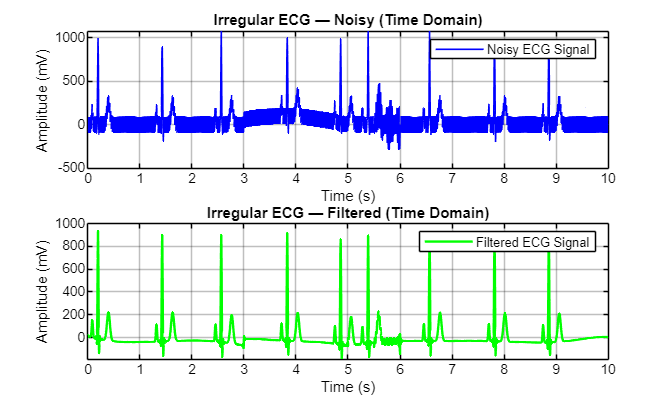


%% =====================================================
%  Irregular Rhythm — Noisy vs Filtered (Time Domain)
%% =====================================================
figure;
subplot(2,1,1);
plot(t_out, ecg_out, 'b', 'LineWidth', 1);
ttl1 = title('Irregular ECG — Noisy (Time Domain)');
xlabel('Time (s)'); ylabel('Amplitude (mV)'); grid on;
set(gca, 'color', 'w', 'XColor', 'k', 'YColor', 'k');
lgd1 = legend('Noisy ECG Signal');
lgd1.Color = 'w'; lgd1.TextColor = 'k'; lgd1.EdgeColor = 'k'; lgd1.FontSize = 8;
ttl1.Color = 'k';

subplot(2,1,2);
plot(t_out, ecg_clean, 'g', 'LineWidth', 1.5);
ttl2 = title('Irregular ECG — Filtered (Time Domain)');
xlabel('Time (s)'); ylabel('Amplitude (mV)'); grid on;
set(gca, 'color', 'w', 'XColor', 'k', 'YColor', 'k');
lgd2 = legend('Filtered ECG Signal');
lgd2.Color = 'w'; lgd2.TextColor = 'k'; lgd2.EdgeColor = 'k'; lgd2.FontSize = 8;
ttl2.Color = 'k';

set(gcf, 'color', 'w');


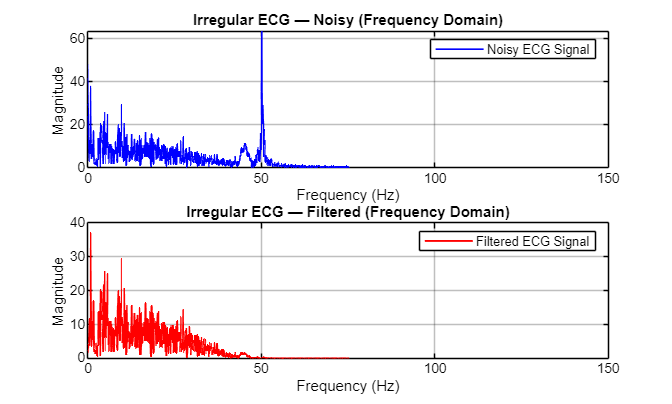

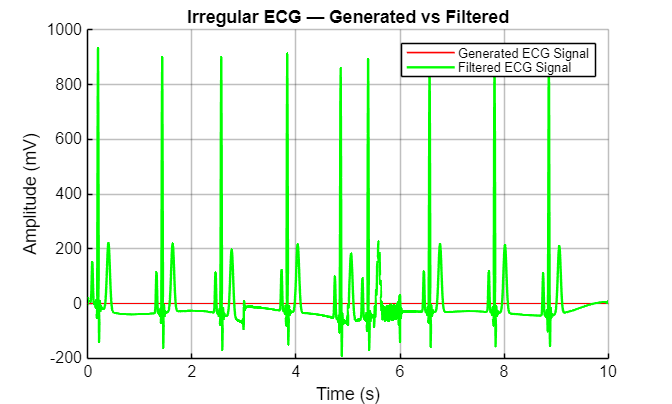


%% =====================================================
%  Irregular Rhythm — Noisy vs Filtered (Frequency Domain)
%% =====================================================
L_f = length(ecg_out);
f_f = fs_out * (0:floor(L_f/2)) / L_f;

P1_noisy = abs(fft(ecg_out)/L_f);
P1_noisy = P1_noisy(1:floor(L_f/2)+1);
P1_noisy(2:end-1) = 2*P1_noisy(2:end-1);

P1_clean = abs(fft(ecg_clean)/L_f);
P1_clean = P1_clean(1:floor(L_f/2)+1);
P1_clean(2:end-1) = 2*P1_clean(2:end-1);

figure;
subplot(2,1,1);
plot(f_f, P1_noisy, 'b', 'LineWidth', 1);
ttl1 = title('Irregular ECG — Noisy (Frequency Domain)');
xlabel('Frequency (Hz)'); ylabel('Magnitude'); grid on;
xlim([0 150]);
set(gca, 'color', 'w', 'XColor', 'k', 'YColor', 'k');
lgd1 = legend('Noisy ECG Signal');
lgd1.Color = 'w'; lgd1.TextColor = 'k'; lgd1.EdgeColor = 'k'; lgd1.FontSize = 8;
ttl1.Color = 'k';

subplot(2,1,2);
plot(f_f, P1_clean, 'r', 'LineWidth', 1.2);
ttl2 = title('Irregular ECG — Filtered (Frequency Domain)');
xlabel('Frequency (Hz)'); ylabel('Magnitude'); grid on;
xlim([0 150]);
set(gca, 'color', 'w', 'XColor', 'k', 'YColor', 'k');
lgd2 = legend('Filtered ECG Signal');
lgd2.Color = 'w'; lgd2.TextColor = 'k'; lgd2.EdgeColor = 'k'; lgd2.FontSize = 8;
ttl2.Color = 'k';

set(gcf, 'color', 'w');
exportgraphics(gcf, 'irregular_ecgNoisyvsFiltered_FreqDomain.png', 'Resolution', 300);

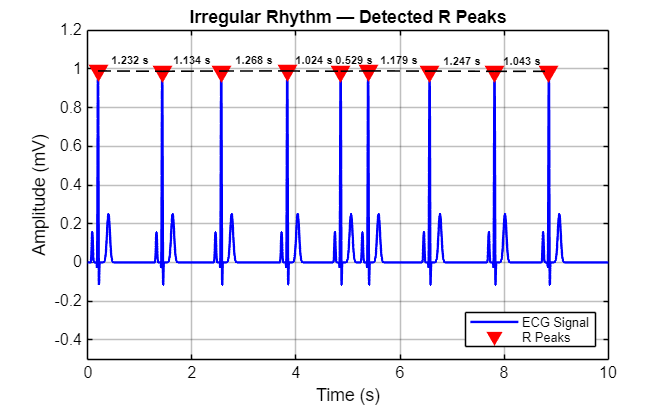


%% =====================================================
%  Irregular Rhythm — R Peak Detection (on filtered signal)
%% =====================================================
figure;
plot(t, ecg, 'b', 'LineWidth', 1.5);
hold on;
plot(t(locs_irr), pks_irr, 'rv', 'MarkerSize', 10, 'MarkerFaceColor', 'r');

%% Draw lines between consecutive R peaks with RR interval labels
for i = 1:length(RR_irr)
    x1 = t(locs_irr(i));
    x2 = t(locs_irr(i+1));
    y1 = pks_irr(i);
    y2 = pks_irr(i+1);
    plot([x1 x2], [y1 y2], 'k--', 'LineWidth', 1);
    xm = (x1 + x2) / 2;
    ym = (y1 + y2) / 2 + 0.05;
    text(xm, ym, sprintf('%.3f s', RR_irr(i)), ...
        'HorizontalAlignment', 'center', ...
        'FontSize', 7, 'Color', 'k', 'FontWeight', 'bold');
end
hold off;

ttl = title('Irregular Rhythm — Detected R Peaks');
xlabel('Time (s)');
ylabel('Amplitude (mV)');
grid on; ylim([-0.5, 1.2]);

set(gcf, 'color', 'w');
set(gca, 'color', 'w', 'XColor', 'k', 'YColor', 'k');

lgd = legend('ECG Signal', 'R Peaks', 'Location', 'southeast');
lgd.Color     = 'w';
lgd.TextColor = 'k';
lgd.EdgeColor = 'k';
lgd.FontSize  = 8;
ttl.Color     = 'k';

exportgraphics(gcf, 'irregularRhythm_RPeaks.png', 'Resolution', 300);

## Generate Graphs

figure;
plot(t, ecg, 'b', 'LineWidth', 1.5);
hold on;
plot(t(locs_irr), pks_irr, 'rv', 'MarkerSize', 10, 'MarkerFaceColor', 'r');

%% Draw lines between consecutive R peaks with RR interval labels
for i = 1:length(RR_irr)
    x1 = t(locs_irr(i));
    x2 = t(locs_irr(i+1));
    y1 = pks_irr(i);
    y2 = pks_irr(i+1);
    plot([x1 x2], [y1 y2], 'k--', 'LineWidth', 1);
    xm = (x1 + x2) / 2;
    ym = (y1 + y2) / 2 + 0.05;
    text(xm, ym, sprintf('%.3f s', RR_irr(i)), ...
        'HorizontalAlignment', 'center', ...
        'FontSize', 7, 'Color', 'k', 'FontWeight', 'bold');
end
hold off;

ttl = title('Irregular Rhythm — Detected R Peaks');
xlabel('Time (s)');
ylabel('Amplitude (mV)');
grid on; ylim([-0.5, 1.2]);

set(gcf, 'color', 'w');
set(gca, 'color', 'w', 'XColor', 'k', 'YColor', 'k');

lgd = legend('ECG Signal', 'R Peaks', 'Location', 'southeast');
lgd.Color     = 'w';
lgd.TextColor = 'k';
lgd.EdgeColor = 'k';
lgd.FontSize  = 8;
ttl.Color     = 'k';

exportgraphics(gcf, 'irregularRhythm_RPeaks.png', 'Resolution', 300);
